# DC Motor Position: State-Space Methods for Controller Design

clear
close all
J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;

A = [0 1 0
    0 -b/J K/J
    0 -K/L -R/L];
B = [0 ; 0 ; 1/L];
C = [1  0  0];
D = 0;
motor_ss = ss(A,B,C,D);

## Prueba de controlabilidad de los estados

sys_order = order(motor_ss)

sys_order = 3

sys_rank = rank(ctrb(A,B))

sys_rank = 2

determinant = det(ctrb(A,B))

determinant = -3.4636e+24

## Prueba de observabilidad de los estados

sys_rank = rank(obsv(A,C))

sys_rank = 3

#### Eligiendo los polos dominantes en lazo cerrado en:

p1 = -100+100i;
p2 = -100-100i;
p3 = -200;

Se satisfacen los requerimientos de diseño porcentaje sobre elongación y tiempo de asentamiento: (ver archivo: seleccion de polos en lazo cerrado1.pdf)

zeta2Mp(0.7071)

ans = 4.3217

#### Cálculo de la matriz de ganancias para retroalimentación de los estados

Kc = place(A,B,[p1 p2 p3])

Kc =     0.0013   -0.0274   -3.9989


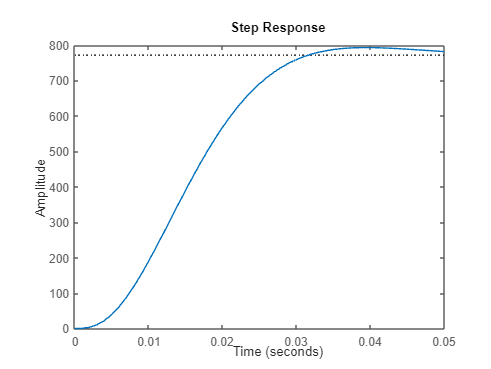

t = 0:0.001:0.05;
sys_cl = ss(A-B*Kc,B,C,D);
step(sys_cl,t)

## Respuesta ante perturbaciones

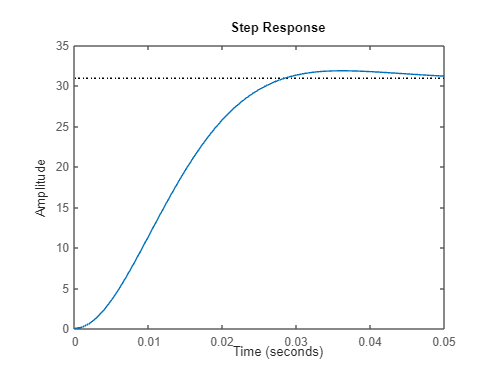

dist_cl = ss(A-B*Kc,[0; 1/J ; 0], C, D);
step(dist_cl,t)

## Añadiendo una acción integral

Podemos modelar la adición de este integrador aumentando nuestras ecuaciones de estado con un estado extra para la integral del error que identificaremos con la variable *w*

Esto agrega una ecuación de estado adicional, donde la derivada de este estado es entonces solo el error *e=y-r. Ver ecuaciones 7-9 en el Control Tutorials for MATLAB and Simulink*

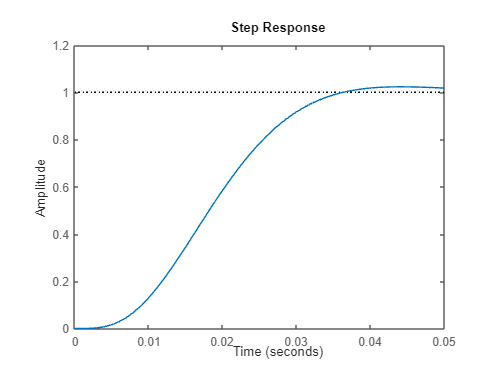

Aa = [0 1 0 0
      0 -b/J K/J 0
      0 -K/L -R/L 0
      1 0 0 0];
Ba = [0 ; 0 ; 1/L ; 0 ];
Br = [0 ; 0 ; 0; -1];
Ca = [1 0 0 0];
Da = [0];

p4 = -300;
Ka = place(Aa,Ba,[p1,p2,p3,p4]);
t = 0:0.001:.05;
sys_cl = ss(Aa-Ba*Ka,Br,Ca,Da);
step(sys_cl,t)

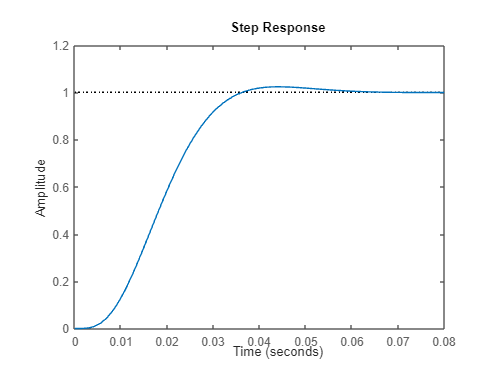

step(sys_cl)

S=stepinfo(sys_cl)

S = struct with fields:
         RiseTime: 0.0201
    TransientTime: 0.0483
     SettlingTime: 0.0483
      SettlingMin: 0.9057
      SettlingMax: 1.0231
        Overshoot: 2.3060
       Undershoot: 0
             Peak: 1.0231
         PeakTime: 0.0442


## Respuesta ante perturbaciones

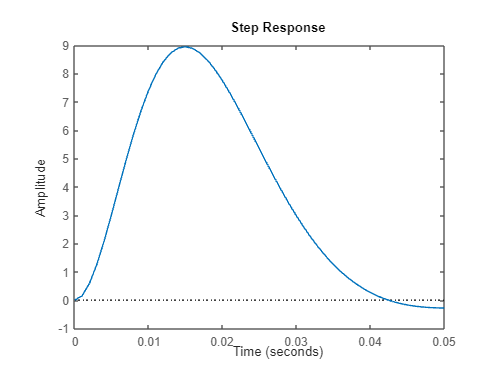

dist_cl = ss(Aa-Ba*Ka,[0 ; 1/J ; 0; 0],Ca,Da);
step(dist_cl,t)

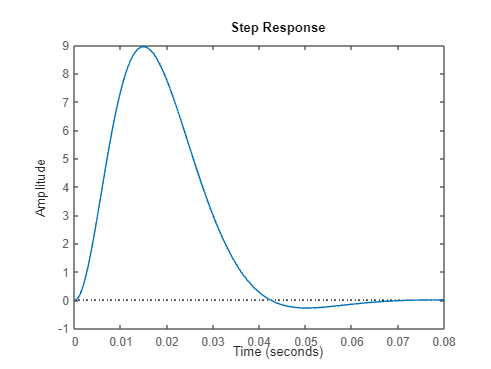

step(dist_cl)